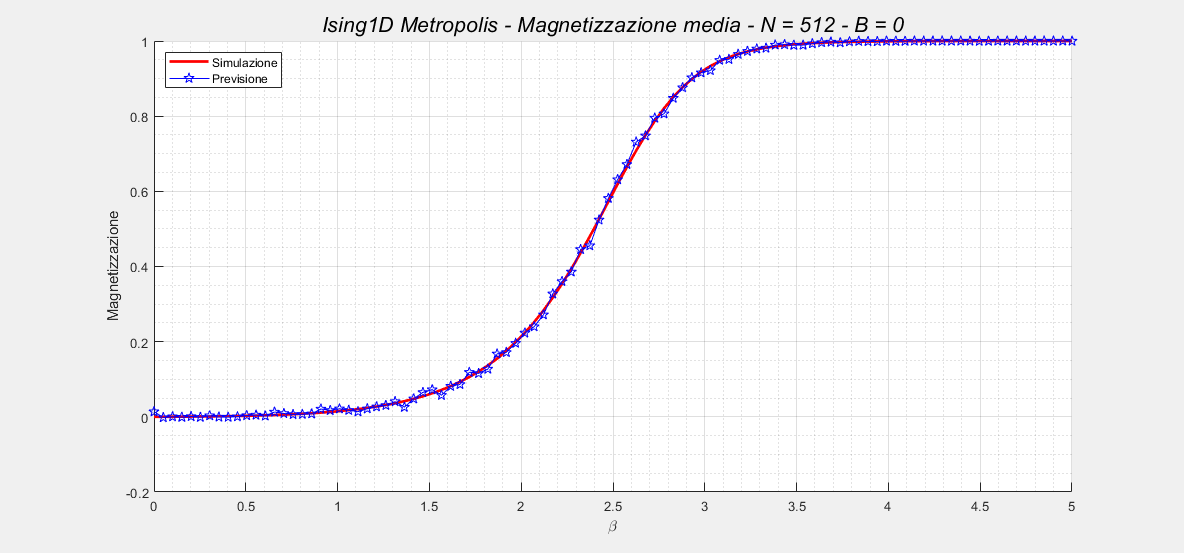

tic
%definisco quantità che userò nel programma
N = 1024;
J = 1;
B = 0.002;
sweeps = 1e5;
therm = 1e3;
beta = linspace(0,5,100);
hw    = waitbar(0,'Musichetta di attesa...'); 
Nbeta = length(beta);
skip = 200;


% Pre-allocazione degli oggetti richiesti per velocizzare il tempo di computazione
Magmedia = zeros([1,floor(sweeps/skip)]); % Definizione del vettore con lunghezza opportuna
Magn     = zeros(size(beta)); % inizializzazione del vettore
errMag   = zeros(size(beta)); % inizializzazione del vettore


spin_pari    = sign(0.5 -rand(1,N/2)); %creo N/2 spin pari
spin_dispari = sign(0.5-rand(1,N/2)); %creo N/2 spin dispari

for cnt = 1:Nbeta
    b = beta(cnt);
    vicini_disp = circshift(spin_dispari,-1); 
    
    for i = 1:therm %termalizzazione
       
       
        %Metropolis per gli spin pari
        
        r = rand(1,N/2);
        dE_pari = 2*J.*spin_pari.*(spin_dispari + vicini_disp +B); %variazione energia
        prob_pari = exp(-dE_pari*b);  %la probabilità è e^-deltaE*beta
       accept = r < prob_pari;        %mossa di metropolis per tutti i pari
       %accept = r < exp(-2*b.*(spin_dispari + vicini_disp + B).*spin_pari);
       spin_pari(accept) = -spin_pari(accept);
        %exp(-2*b(cnt) .* (spin_dispari + vicini_disp + B).*spin_pari);
        
        %Metropolis per gli spin dispari
        vicini_pari = circshift(spin_pari, 1);
        
        r = rand(1,N/2);
        dE_dispari = 2*J.*spin_dispari.*(spin_pari + vicini_pari +B); %variazione energia
        prob_dispari = exp(-dE_dispari*b);
        accept = r < prob_dispari;
        %accept = r < exp(-2*b.*(spin_pari + vicini_pari + B).*spin_dispari);
        spin_dispari(accept) = -spin_dispari(accept);
        
    end
    
    %Inizio evoluzione sistema
    
    for s = 1:sweeps
         vicini_disp = circshift(spin_dispari,-1); 
        r = rand(1,N/2);
       dE_pari = 2*J.*spin_pari.*(spin_dispari + vicini_disp +B); %variazione energia
       prob_pari = exp(-dE_pari*b);  %la probabilità è e^-deltaE*beta
       accept = r < prob_pari;        %mossa di metropolis per tutti i pari
       %accept = r < exp(-2*b.*(spin_dispari + vicini_disp + B).*spin_pari);
       spin_pari(accept) = -spin_pari(accept);
        %exp(-2*b(cnt) .* (spin_dispari + vicini_disp + B).*spin_pari);
        
        %Metropolis per gli spin dispari
        vicini_pari = circshift(spin_pari, 1);
        
        r = rand(1,N/2);
        dE_dispari = 2*J.*spin_dispari.*(spin_pari + vicini_pari +B); %variazione energia
        prob_dispari = exp(-dE_dispari*b);
        accept = r < prob_dispari;
        %accept = r < exp(-2*b.*(spin_pari + vicini_pari + B).*spin_dispari);
        spin_dispari(accept) = -spin_dispari(accept);
        if rem(s,skip) == 0
             Magmedia(s/skip) = (sum(spin_pari)+sum(spin_dispari))/(N);
        end
       
        
    end
    Magn(cnt) = mean(Magmedia);         %magnetizzazione media per spin
    errMag(cnt) = std(Magmedia);        %errore sulla magnetizzazione media
    
    waitbar(cnt/Nbeta);
    %dE = 2*J*spin(row,col)*sum(vicini); 
end
close(hw);


%momento grafici
ms = sinh(B.*beta)./sqrt(sinh(B.*beta).^2+exp(-4.*beta)); % magnetizzazione teorica

graf1=figure; % prima figura
    set(graf1,'Windowstyle','docked') % Mettiamola 'docked'
    title(['Ising1D Metropolis - Magnetizzazione media - N = 512 ',...
           '- B = 0'],...
          'FontSize',16,'FontWeight','normal','FontAngle','it') 
    grid on 
    grid minor % grigla fitta
    hold on    
plot(beta,ms,'r-','LineWidth',2) % Plot della magnetizzazione scondo la formula esatta
    xlabel('\beta')
    ylabel('Magnetizzazione')          
   
    
%     errorbar(beta,Magn,errMag./sqrt(sweeps/skip),...
%              'Color','blue','LineStyle','-','Marker','p',...
%              'MarkerSize',8)
    plot(beta,Magn,...
             'Color','blue','LineStyle','-','Marker','p',...
             'MarkerSize',8)
    if B < 0
       legend({'Simulazione','Previsione'},'Location','NorthEast') %
       % Mettiamo la legenda in modo che non intralci il diagramma
    else
       legend({'Simulazione','Previsione'},'Location','NorthWest') 
    end



tempo2 = toc;